# EE320 - Filtering and Source Separation

## Setup

%% Setup
close all
clear
StudRegNum = 202118874; % My reg number
[x1,x2] = AssignmentScenario(StudRegNum); % generating specific signal to me

## Question 1

*Estimation of interference frequency in time domain. First 50 samples have no speakers, interference dominates here:*

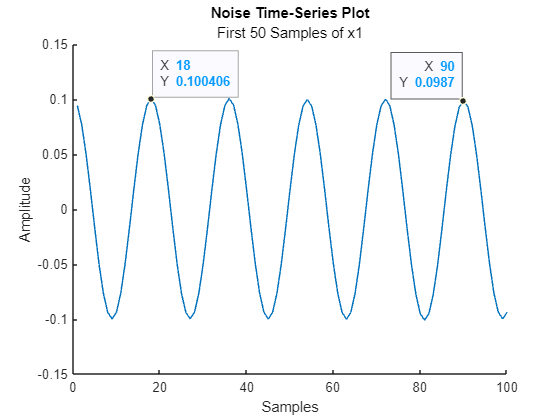

%% Q1
q1_x1_int_analysis = x1(1:100,1); %get first 50 samples

figure
hold on 
plot(1:100,q1_x1_int_analysis);
title("Noise Time-Series Plot", "First 50 Samples of x1");
xlabel("Samples");
ylabel("Amplitude");

ax = gca;
chart = ax.Children(1);
datatip(chart,18,0.1004);
datatip(chart,90,0.0987);
hold off


$$f_{\textrm{noise}} =\frac{N_{\textrm{waves}} }{N_{\textrm{samples}} \times T_{\textrm{sample}} }=\frac{N_{\textrm{waves}} \times f_s }{N_{\textrm{samples}} }=\frac{4\times 8000}{72}=444\ldotp 44\textrm{Hz}$$


## Question 2

*Estimation of interference frequency in fourier domain*

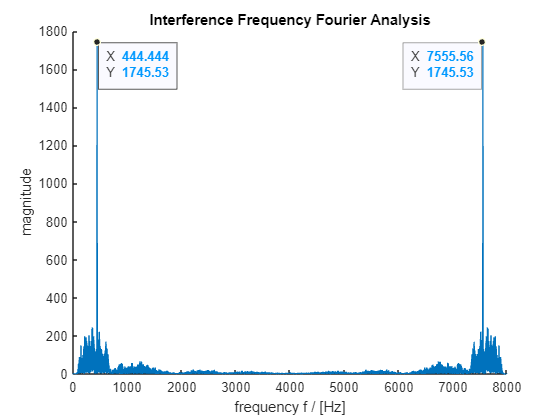

%% Q2
% Code provided by assignment document ----------------
fs = 8000; % sampling frequency in Hertz
f = (0:length(x1)-1)/length(x1)*fs; % frequency scale

figure %FFT plot
hold on
title("Interference Frequency Fourier Analysis")
plot(f,abs(fft(x1))); % discrete Fourier transform of x
xlabel('frequency f / [Hz]'); % label axes
ylabel('magnitude');
% end provided code -----------------------------------
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,7555.56,1799);
datatip(chart2,444.444,1799);
hold off

There are two prominent peaks in the spectrum: One at 444 Hz, the other at ~7.6 kHz. Due to the Nyquist theorem:

$f_s \ge B$ where B is the bandwidth of the sampled signal, we can disregard anything above 4 kHz as aliasing. 

Thus: $f_o =444\ldotp 44\textrm{Hz}\;$can be used with a high certainty.

## Question 3

*Time delay analysis in the time domain*

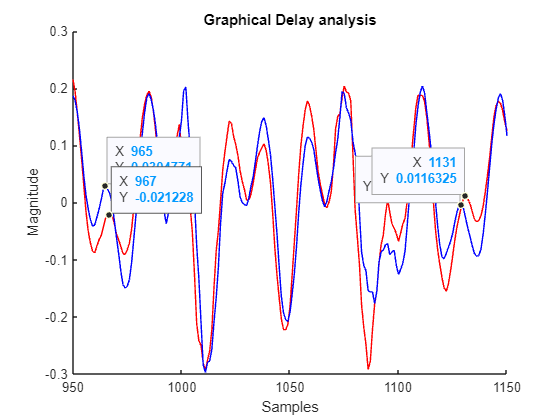

%% Q3
Q3_s1only_range = 19500:21548; % range of samples where only speaker 1 is speaking
q3_x1_s1only = x1(Q3_s1only_range,1); %subset of each signal at this time
q3_x2_s1only = x2(Q3_s1only_range,1);

%Graphing both signals on top of each other
figure
hold on
title("Graphical Delay analysis");
xlabel("Samples")
ylabel("Magnitude")
q3_x1plot = plot(q3_x1_s1only);
q3_x1plot.Color = "Red";
q3_x2plot = plot(q3_x2_s1only);
q3_x2plot.Color = "Blue";

ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,1169,-0.1656);
datatip(chart3,1129,-0.002814);
datatip(chart3,965,0.03048);
chart3 = ax3.Children(2);
datatip(chart3,1131,0.01163);
datatip(chart3,967,-0.02123);
xlim([950 1150])
hold off

Zoom into the above graph to see the delay clearer. For speaker 1: x1 seems to lag x2 by about 2 samples. This corresponds to about 0.25 ms.

Thus: $\tau_{1,1} =2\ldotp 5\times {10}^{-4} \;\textrm{and}\;\tau_{1,2} =0$

There is also a clear difference in attenuation between x2 and x1.

## Question 4

*Analysis of gain/attenuation and angle in fourier domain.*


$$\textrm{let}\;x\left\lbrack n\right\rbrack \longrightarrow X\left\lbrack e^{j\Omega } \right\rbrack$$


If only speaker 1 is present, and noise is assumed to be the same between each microphone. There will also be an attenuation from path loss as the signal travels. We will take the first microphone it is incident on as a baseline, thus $\rho_{1,2} =1\ldotp$ Given more information, perhaps a third microphone, the distance to the speaker from receivers could be calculated. This is beyond the scope of this assignment.


$$x_1 \left\lbrack n\right\rbrack ={\rho_{1,1} x}_2 \left\lbrack n-\tau_{1,1} \right\rbrack$$



$$x_2 \left\lbrack n\right\rbrack \longrightarrow X_2 \left\lbrack e^{j\Omega } \right\rbrack$$


$x_2 \left\lbrack n-\tau_{1,1} \right\rbrack \longrightarrow {{\rho_{1,1} e}^{j\Omega \tau_{1,1} } X}_2 \left\lbrack e^{j\Omega } \right\rbrack$ (see note)

$\Rightarrow \frac{X_2 \left\lbrack e^{j\Omega } \right\rbrack }{X_1 \left\lbrack e^{j\Omega } \right\rbrack }=\frac{X_2 \left\lbrack e^{j\Omega } \right\rbrack }{{{\rho_{1,1} e}^{j\Omega \tau_{1,1} } X}_2 \left\lbrack e^{j\Omega } \right\rbrack }={\frac{1}{\rho_{1,1} }e}^{-j\Omega \tau_{1,1} } \cdot \frac{X_2 \left\lbrack e^{j\Omega } \right\rbrack }{X_2 \left\lbrack e^{j\Omega } \right\rbrack }$ = ${\frac{1}{\rho_{1,1} }e}^{-j\Omega \tau_{1,1} }$

$\Rightarrow \angle \left(\frac{X_2 \left\lbrack e^{j\Omega } \right\rbrack }{X_1 \left\lbrack e^{j\Omega } \right\rbrack }\right)$=$\angle$($e^{-j\Omega \tau_{1,1} }$) = $-\Omega \tau_{1,1} =-2\pi f\tau_{1,1}$

$\textrm{and}\;$$|$$\frac{X_2 \left\lbrack e^{j\Omega } \right\rbrack }{X_1 \left\lbrack e^{j\Omega } \right\rbrack }|$= $|$${\frac{1}{\rho_{1,1} }e}^{-j\Omega \tau_{1,1} }$$|$=$\frac{1}{\rho_{1,1} }$  Thus giving the attenuation due to the delay. 

If $\rho >1,$ $x_2$ and $x_1$are backwards. The same goes for a phase greater than 0. This can be fixed by taking the reciprocal of $\rho$ or multiplying the phase angle by -1. 

If $\rho =1$for both signals and the phase is 0, the speaker must be directly forward of the receiver.

Note:


$$a\left(t\right)\times b$$

$$\longrightarrow A\left\lbrack e^{j\Omega } \right\rbrack *B$$


if b is a constant the transform will be a dirac delta function, of magnitude b


$$b\longrightarrow b\times \delta \left(f\right)$$


Therefore:


$$A\left\lbrack e^{j\Omega } \right\rbrack *B=b\times A\left\lbrack e^{j\Omega } \right\rbrack$$


## Question 5

*Using previous analysis to find gain and phase for speaker 1*

### *Gain*

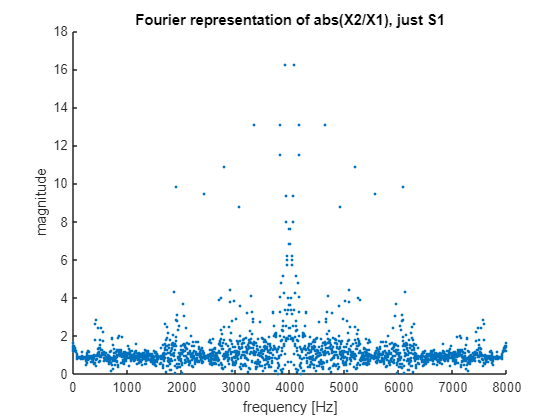

%% Q5 - Gain

q5_s1only_range = 19500:21548; %range of samples with only speaker 1
q5_s1only_X1 = fft(x1(q5_s1only_range)); %fft of each signal
q5_s1only_X2 = fft(x2(q5_s1only_range));

q5_s1only_G = abs(q5_s1only_X2./q5_s1only_X1); %G = abs(X2/X1)
q5_N = length(q5_s1only_range);
q5_fscale = (0:(q5_N-1))/q5_N*fs; % frequency scale

figure
hold on
plot(q5_fscale,q5_s1only_G,"."); % plot magnitude of coefficient
title("Fourier representation of abs(X2/X1), just S1");
xlabel('frequency [Hz]'); % label axes
ylabel('magnitude');
hold off

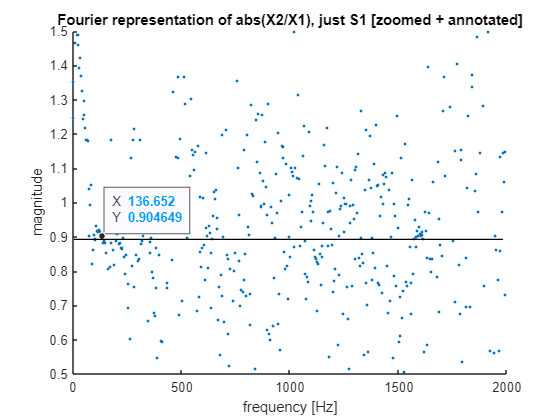


figure
hold on
plot(q5_fscale,q5_s1only_G,"."); % plot magnitude of coefficients
title("Fourier representation of abs(X2/X1), just S1 [zoomed + annotated]");
xlabel('frequency [Hz]'); % label axes
ylabel('magnitude');

%annotations
annotation("line", [0.1321 0.8982], [0.43 0.43]) %rough line fit for dense clusters

%datatip
ax4 = gca;
chart4 = ax4.Children(1);
datatip(chart4,152.2,0.9);

%zoom in graph
xlim([0 2000])
ylim([0.5 1.5])
hold off

The resulting magnitude plot is very spikey, but we would expect an overall offset from 1 by the time delay attenuation.

A zoom in to the plot shows a rough magnitude of around 0.9, we can examine it further by looking at a histogram of the first few thousand samples

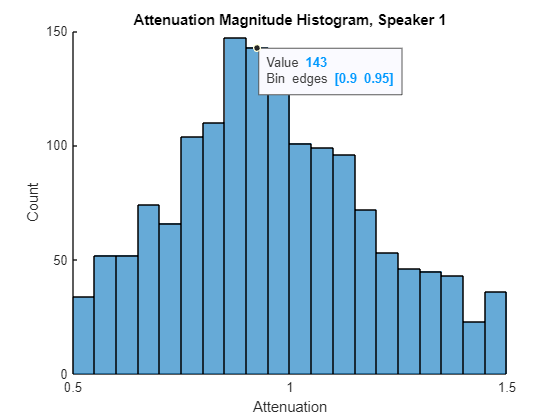

figure
hold on
title("Attenuation Magnitude Histogram, Speaker 1")
histogram(q5_s1only_G(1:2000,1),"BinWidth",0.05);
xlabel("Attenuation");
ylabel("Count")

%only look at biggest bins
xlim([0.5 1.5]);

%data tip at peak
ax5 = gca;
chart5 = ax5.Children(1);
datatip(chart5,0.925,143);

hold off;

The two most populous bins are 0.85-> 0.9 and 0.9->0.95. We can be reasonably sure that the gain lies around 0.9

To get a better value for this we can take an average of the values falling into this range: $0\ldotp 5\to 1\ldotp 5$.

%averaging over interval 0.5 <= abs(X2/X1) <= 1.5
q5_mag_interval_samples = q5_s1only_G(1:2000,1);
q5_mag_average_interval = mean(q5_mag_interval_samples((q5_mag_interval_samples >= 0.5) & (q5_mag_interval_samples <= 1.5) ));
fprintf("Average magnitude between 0.5 and 1.5 is: %.3f",q5_mag_average_interval);

Average magnitude between 0.5 and 1.5 is: 0.962

Thus, $\rho_{1,1} =0\ldotp 962$.

### Phase

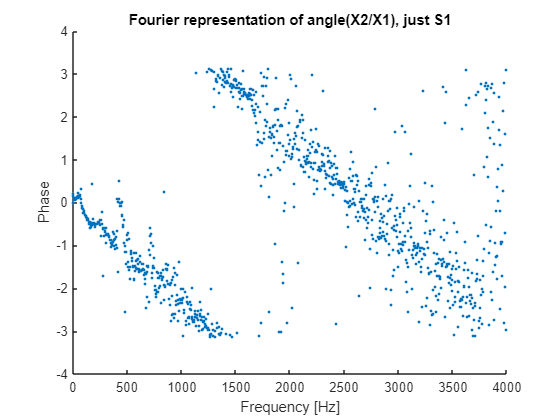

q5_s1only_A = angle(q5_s1only_X2./q5_s1only_X1); %A = angle(X2/X1)

figure
hold on
plot(q5_fscale,q5_s1only_A,"."); % plot phase 
title("Fourier representation of angle(X2/X1), just S1");
xlabel('Frequency [Hz]'); % label axes
ylabel('Phase');

xlim([0 4000]); %everything above 4000 is aliasing
hold off

Currently not too meaningful, as it wraps, can use unwrap to fix that

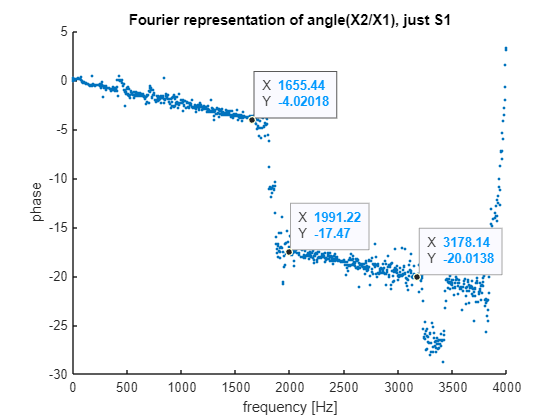

figure
hold on
plot(q5_fscale,unwrap(q5_s1only_A),"."); % plot phase 
title("Fourier representation of angle(X2/X1), just S1");
xlabel('frequency [Hz]'); % label axes
ylabel('phase');

xlim([0 4000]); %everything above 4000 is aliasing

%datatips at two continuous sections
ax6 = gca;
chart6 = ax6.Children(1);
datatip(chart6,3178,-20.01);
datatip(chart6,1991,-17.47);
datatip(chart6,1655,-4.02);
hold off

The ideal response would be a simple linear line, however there is noise on both signals causing these discontinuities in the graph. Ignoring the discontinuities, the gradient is mostly constant. 

Previous analysis showed:

 
$$\angle \left(\frac{X_2 \left\lbrack e^{j\Omega } \right\rbrack }{X_1 \left\lbrack e^{j\Omega } \right\rbrack }\right)=-\Omega \tau_{1,1} =-2\pi f\times \tau_{1,1} \;$$



$$\Rightarrow m=-2\pi \times \tau_{1,1} \;$$


A linear fit of the two largest continuous sections of the graph should each have a roughly equal gradient.

%taking two linear fits:
%q5 fscale is in sample bins, need to convert our x axis values accordingly:

%cont1 goes from 1 -> 1650Hz, 
%use (1650/8000)*2049 to convert to our bins
% =~ 423
q5_phase_continuity1 = 1:423;
%cont2 : 1991 to 3170
%=> 510 to 812
q5_phase_continuity2 = 510:812;

q5_phase_linfit1 = polyfit(q5_fscale(q5_phase_continuity1), ...%x axis frequency
                           unwrap(q5_s1only_A(q5_phase_continuity1)), ... %y axis is phase
                           1 ... %degree 1
                           );


q5_phase_linfit2 = polyfit(q5_fscale(q5_phase_continuity2), ...%x axis frequency
                           unwrap(q5_s1only_A(q5_phase_continuity2)), ... %y axis is phase
                           1 ... %degree 1
                           );
%have a look at those gradients!
fprintf("Gradient 1 = %.4f \n",q5_phase_linfit1(1,1));

Gradient 1 = -0.0024 


fprintf("Gradient 2 = %.4f \n",q5_phase_linfit2(1,1));

Gradient 2 = -0.0024 


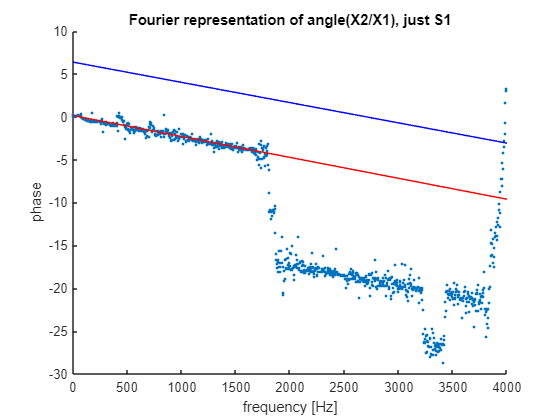

%now lets plot these back onto the graph:

figure
hold on
plot(q5_fscale,unwrap(q5_s1only_A),"."); % plot phase 
title("Fourier representation of angle(X2/X1), just S1");
xlabel('frequency [Hz]'); % label axes
ylabel('phase');

plot(q5_fscale,polyval(q5_phase_linfit1,q5_fscale),"-","Color","red");
plot(q5_fscale,polyval(q5_phase_linfit2,q5_fscale),"-","Color","Blue");
xlim([0 4000]); %everything above 4000 is aliasing
hold off

The y-intercept is quite off (this will be an error in my graphing). However, the gradients are equal at -0.0024


$$\begin{array}{l}
m=-2\pi \times \tau_{1,1} \;\\
{\Rightarrow \;\tau }_{1,1} =\frac{m}{-2\pi }=\frac{-0\ldotp 0024}{-2\pi }=382\mu s=3\;\textrm{samples}
\end{array}$$


This is very similar to our previous estimate of 2 samples.

### Angle estimation

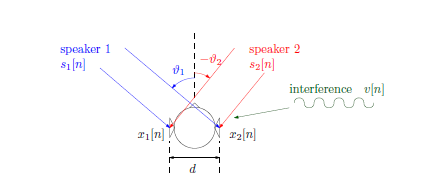

Figure 1: Situation - As provided in assignment document

The distance is provided:


$$d=17\ldotp 15\textrm{cm}$$


Let's take the case of a single speaker, speaker 1.

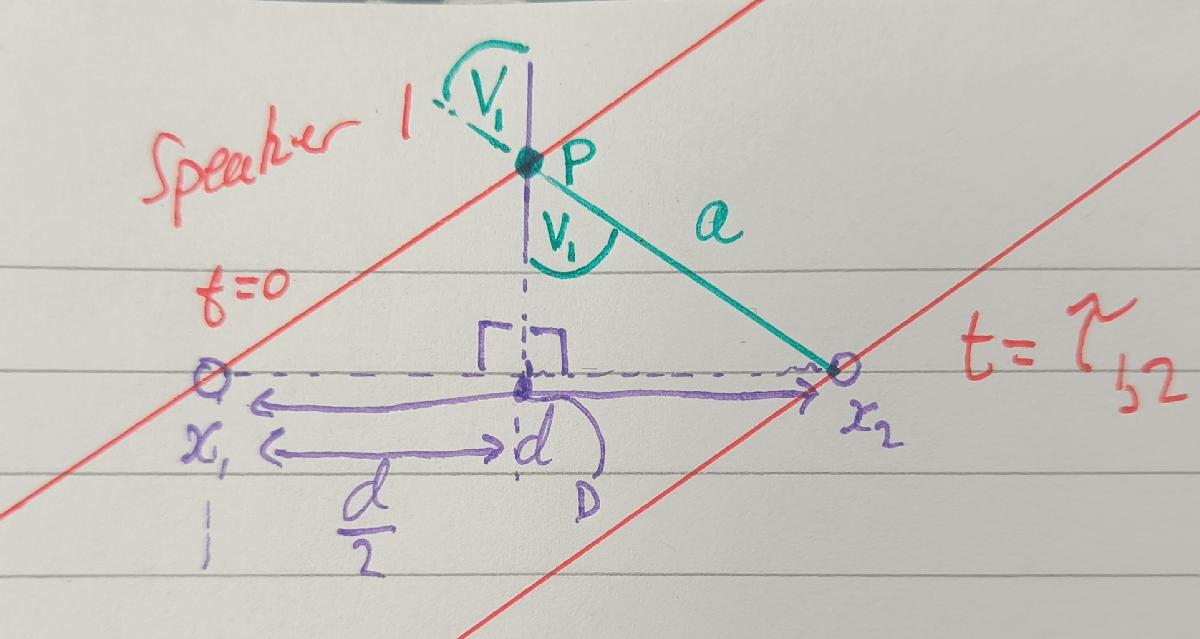

Figure 2: Diagram of speaker 1 only

A point half way between $x_1$ and $x_2$ is marked D.

A line is drawn vertically from this point to where it intersects the sound front (treated as a plane). This point is called P. The angle of the speaker from this point is called $\nu_1$. The distance $x_2 \to P=x_1 \to P$. Thus, due to the properties of cross angles, $\angle x_2 \textrm{PD}$must be $\nu_1 \;$as well.

In this case, speaker 1 hits x2 first, so the diagram is actually the mirror of the actual data. The same analysis applies.

As this is a sound wave, it will move at 343m/s, thus:


$$\begin{array}{l}
\textrm{distance}=\textrm{velocity}\times \textrm{time}\\
a=343{\textrm{ms}}^{-1} \times 382\times {10}^{-6} =13\ldotp 1cm
\end{array}$$


Now that two sides of the right triangle are known, $\nu_1$ can be calculated.


$$\begin{array}{l}
\sin \left(\nu_1 \right)=\frac{\textrm{Opp}}{\textrm{hyp}}=\frac{\frac{d}{2}}{a}=\frac{17\ldotp 15}{2\times 13\ldotp 1}\\
\nu_1 =40\ldotp 9\degree 
\end{array}$$


For simplicity angles of signals hitting $x_2$ first and thus coming from the right, will be represented as positive. Angles of signals hitting $x_1$ first and thus coming from the left will be represented as negative.

### Q5 Results Summary


$$\begin{array}{l}
\;\tau_{1,1} =\;382\mu s=3\;\textrm{samples}\\
\;\tau_{1,2} =0\\
\rho_{1,1\;} =0\ldotp 962\\
\rho_{1,2} =1\\
\nu_1 =40\ldotp 9\degree \\
\;
\end{array}$$


## Question 6 

*Doing it all again for speaker 2!*

%% Q6
q6_Range = (24800:25824);
q6_x1 = x1(q6_Range);
q6_x2 = x2(q6_Range);
q6_N = length(q6_Range);
q6_f = (0:(q6_N-1))/q6_N*fs; %fs is still 8000

q6_X1 = fft(q6_x1);
q6_X2 = fft(q6_x2);

q6_G = abs(q6_X2./q6_X1);
q6_A = unwrap(angle(q6_X2./q6_X1));


### Gain

As before, plotting abs(X2./X1)

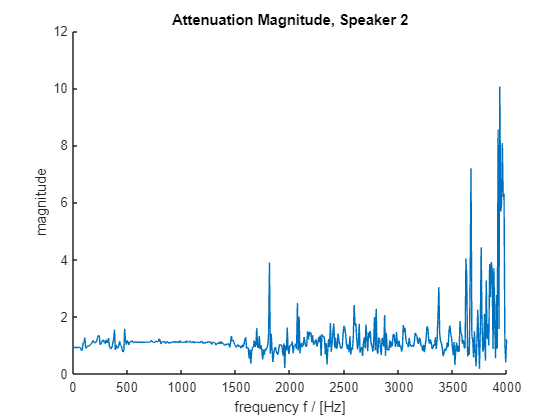

figure
hold on
title("Attenuation Magnitude, Speaker 2");
plot(q6_f,q6_G); % plot magnitude of coefficient
xlabel('frequency f / [Hz]'); % label axes
ylabel('magnitude');

xlim([0,4000]);
hold off

Very spikey again! Let's take a histogram to get a better idea:

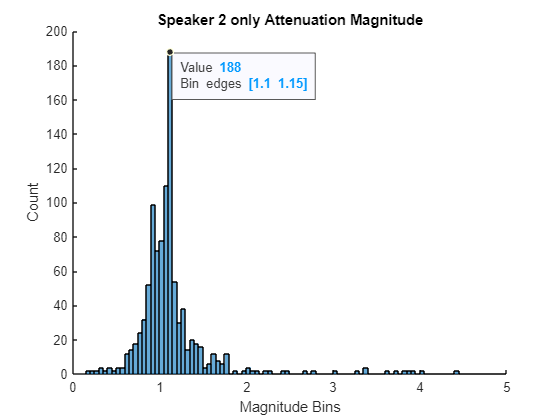

figure
hold on
histogram(q6_G,"BinWidth",0.05);

%only look at biggest bins
xlim([0 5]);
xlabel("Magnitude Bins");
ylabel("Count");
title("Speaker 2 only Attenuation Magnitude")

ax7 = gca;
chart7= ax7.Children(1);
datatip(chart7,1.1,188);
hold off;

Very large peak at the 1.1->1.15 bin.

Again, we can take an average around this peak to get a better value:

%peak is at around 0.55 -> 1.8
q6_mag_interval_samples = q6_G(1:512,1);
q6_mag_average_interval = mean(q6_mag_interval_samples((q6_mag_interval_samples >= 0.55) & (q6_mag_interval_samples <= 1.8) ));
fprintf("Average magnitude between 0.5 and 1.5 is: %.3f",q6_mag_average_interval);

Average magnitude between 0.5 and 1.5 is: 1.081

fprintf("Reciprocal: %.3f",1/q6_mag_average_interval);

Reciprocal: 0.925

The gain given was over 1, so we took the reciprocal to get $\rho_{2,2} =0\ldotp 925$.

### Phase

first we'll plot in time domain to see what lags what

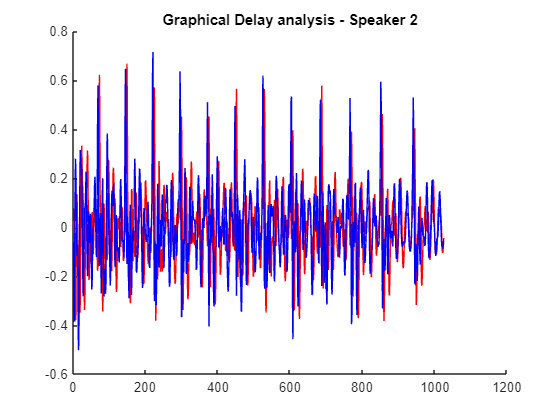

%% q6 - phase
%Graphing both signals on top of each other
figure
hold on
title("Graphical Delay analysis - Speaker 2");
q6_x1plot = plot(q6_x1);
q6_x1plot.Color = "Red";
q6_x2plot = plot(q6_x2);
q6_x2plot.Color = "Blue";

hold off;

Zoom in for clarity:

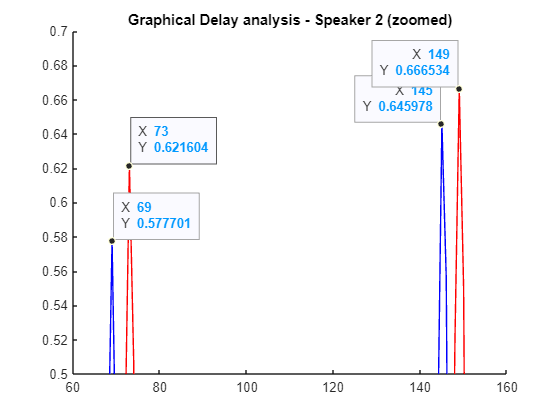

%wee zoom in for a treat
figure
hold on
title("Graphical Delay analysis - Speaker 2 (zoomed)");
q6_x1plot = plot(q6_x1);
q6_x1plot.Color = "Red";
q6_x2plot = plot(q6_x2);
q6_x2plot.Color = "Blue";

xlim([60,160]);
ylim([0.5,0.7]);

ax8 = gca;
chart8 = ax8.Children(1);
datatip(chart8,145,0.646);
datatip(chart8,69,0.5777);
chart8 = ax8.Children(2);
datatip(chart8,149,0.6665);
datatip(chart8,73,0.6216);

hold off;

x1 seems to lag x2 by 4 samples for this.

Let's double check with some fourier analysis:

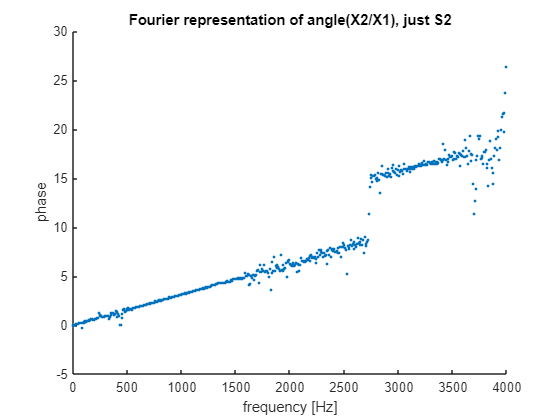

figure
hold on
plot(q6_f,q6_A,"."); % plot phase 
title("Fourier representation of angle(X2/X1), just S2");
xlabel('frequency [Hz]'); % label axes
ylabel('phase');

xlim([0 4000]);
hold off;

Only looking below nyquist point. There are two clear continuous regions, we will take the gradient of each and compare.

%Range 1: 0:2669, range 2: 2810:3590.
%Each needs to be converted to our fft bins:
%((sample)/8000)*amount of bins:
%(2669/8000)*1025 = 342
%2810 -> 360
%3590 -> 460

q6_cont1_range = 1:342;
q6_cont2_range = 360:460;


q6_phase_linfit1 = polyfit(q6_f(q6_cont1_range), ...%x axis frequency
                           q6_A(q6_cont1_range), ... %y axis is phase
                           1 ... %degree 1
                           );


q6_phase_linfit2 = polyfit(q6_f(q6_cont2_range), ...%x axis frequency
                           unwrap(q6_A(q6_cont2_range)), ... %y axis is phase
                           1 ... %degree 1
                           );

fprintf("Gradient 1 = %.4f \n",q6_phase_linfit1(1,1));

Gradient 1 = 0.0031 


fprintf("Gradient 1 = %.4f \n",q6_phase_linfit2(1,1));

Gradient 1 = 0.0029 


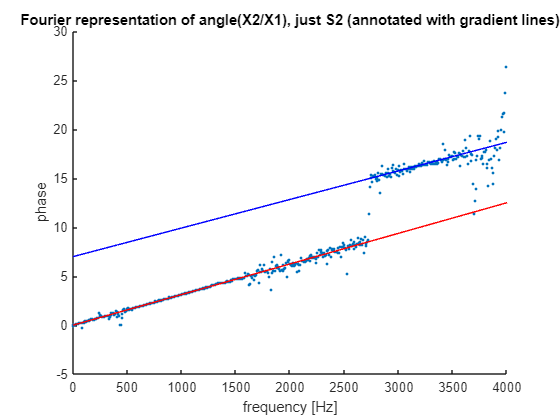

figure
hold on
title("Fourier representation of angle(X2/X1), just S2 (annotated with gradient lines)");
xlabel('frequency [Hz]'); % label axes
ylabel('phase');

plot(q6_f,q6_A,"."); % plot phase 

plot(q6_f,polyval(q6_phase_linfit1,q6_f),"-","Color","red");
plot(q6_f,polyval(q6_phase_linfit2,q6_f),"-","Color","Blue");
xlim([0 4000]); %everything above 4000 is aliasing
hold off

The two gradients are 0.0031 and 0.0029 respectively for the two continuous regions. We can take the average of these and get 0.0030.

As previous:


$$\begin{array}{l}
m=-2\pi \tau \\
\tau =\frac{m}{-2\pi }=\frac{0\ldotp 0030}{-2\pi }=-477\ldotp 46\mu s=-3\ldotp 8\;\textrm{samples}\Rightarrow -4\;\textrm{samples}
\end{array}$$


This gives the amount x2 lags x1, as it is negative we can convert this to a delay of 4 samples.

### Angle Calculation

All of the previous analysis in question 5 holds for finding $\nu_2$.


$$\begin{array}{l}
\textrm{distance}=\textrm{velocity}\times \textrm{time}\\
a=343{\textrm{ms}}^{-1} \times 477\ldotp 46\times {10}^{-6} =16\ldotp 4cm
\end{array}$$


Now that two sides of the right triangle are known, $\nu_1$ can be calculated.


$$\begin{array}{l}
\sin \left(\nu_1 \right)=\frac{\textrm{Opp}}{\textrm{hyp}}=\frac{\frac{d}{2}}{a}=\frac{17\ldotp 15}{2\times 16\ldotp 4}\\
\nu_2 =31\ldotp 5\degree 
\end{array}$$


As mentioned previously, signals coming in from the left will be treated as negative, therefore: 


$$\nu_2 =-31\ldotp 5\degree$$


### Summary of speaker 2 values.


$$\begin{array}{l}
\;\tau_{2,1} =0\\
\;\tau_{2,2} =477\ldotp 46\mu s=4\;\textrm{samples}\\
\rho_{2,1\;} =1\\
\rho_{2,2} =0\ldotp 925\\
\nu_2 =-31\ldotp 5\degree \\
\;
\end{array}$$


## Question 7

### Summary of relevant values:


$$\begin{array}{l}
\;\tau_{2,1} =0\\
\;\tau_{2,2} =477\ldotp 46\mu s=4\;\textrm{samples}\\
\rho_{2,1\;} =1\\
\rho_{2,2} =0\ldotp 925
\end{array}$$



$$\begin{array}{l}
\;\tau_{1,1} =\;382\mu s=3\;\textrm{samples}\\
\;\tau_{1,2} =0\\
\rho_{1,1\;} =0\ldotp 962\\
\rho_{1,2} =1\;
\end{array}$$


### Derivation of H(z)

As provided in assignment brief:


$$\begin{array}{l}
x\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack \times s\left\lbrack n\right\rbrack \\
\left\lbrack \begin{array}{c}
x_1 \left\lbrack n\right\rbrack \\
x_2 \left\lbrack n\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
h_{1,1} \left\lbrack n\right\rbrack  & h_{1,2} \left\lbrack n\right\rbrack \\
h_{2,1} \left\lbrack n\right\rbrack  & h_{2,2} \left\lbrack n\right\rbrack 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
s_1 \left\lbrack n\right\rbrack \\
s_2 \left\lbrack n\right\rbrack 
\end{array}\right\rbrack 
\end{array}$$


Where n is a discrete sample. $s_1 ,s_2$ are the original speech signals and $h_{i,j}$ are the transfer functions defined as follows:


$$h_{i,j} =\rho_{i,j} \times \delta \left\lbrack n-\tau_{i,j} \right\rbrack$$


Additonally: i represents the microphone and j represents the speaker.

The z transform of a function is defined as follows:


$$X\left\lbrack z\right\rbrack =\sum_{n=0}^{\infty } x\left\lbrack n\right\rbrack z^{-n}$$


The transform of any of the defined transfer functions would be as follows:


$$H\left\lbrack z\right\rbrack =$$

$$\sum_{n=0}^{\infty } \left(\rho \times \delta \left\lbrack n-\tau \right\rbrack \right)z^{-n}$$


The dirac delta function is defined as:


$$\delta \left\lbrack n\right\rbrack =1\;\textrm{if}\;n=0,0\;\textrm{otherwise}$$


Therefore:

$\delta \left\lbrack n-\tau \right\rbrack =1\;\textrm{if}\;n=\tau ,0\;\textrm{otherwise}$.

Relating this back to our z transform: The only non-zero term must be at $n=\tau$.


$$H^{\prime } \left\lbrack z\right\rbrack =\rho z^{-\tau }$$


In matrix form:


$$H\left\lbrack z\right\rbrack =\left\lbrack \begin{array}{cc}
\rho_{1,1} z^{-\tau_{1,1} }  & \rho_{1,2} z^{-\tau_{1,2} } \\
\rho_{2,1} z^{-\tau_{2,1} }  & \rho_{2,2} z^{-\tau_{2,1} } 
\end{array}\right\rbrack$$


For the first receiver that each signal is incident on, we took the attenuation as 1 and the delay as 0. This means that each of these terms will be 1.

Filling in the matrix now.


$$H\left\lbrack z\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 962z^{-3}  & 1\\
1 & 0\ldotp 925z^{-4} 
\end{array}\right\rbrack$$


## Question 8

In the z domain, the overall system would look as follows, where $Y\left\lbrack z\right\rbrack$ is $S\left\lbrack z\right\rbrack$ with noise.


$$X\left\lbrack z\right\rbrack =H\left\lbrack z\right\rbrack Y\left\lbrack z\right\rbrack$$


To recover the original signal $S\left\lbrack z\right\rbrack$, we can premultiply each side by $H^{-1} \left\lbrack z\right\rbrack$. This inverse will be defined as $G\left\lbrack z\right\rbrack \ldotp$ This would look like:


$$G\left\lbrack z\right\rbrack X\left\lbrack z\right\rbrack =Y\left\lbrack z\right\rbrack$$


The inverse of a 2x2 matrix is as follows:


$$\begin{array}{l}
A=\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack \\
A^{-1} =\frac{1}{\textrm{ad}-\textrm{bc}}\left\lbrack \begin{array}{cc}
d & -b\\
-c & a
\end{array}\right\rbrack 
\end{array}$$


Therefore:


$$G\left\lbrack z\right\rbrack =\frac{1}{\left(0\ldotp 962\times 0\ldotp 925\right)z^{-7} -1}\left\lbrack \begin{array}{cc}
0\ldotp 925z^{-4}  & -1\\
-1 & 0\ldotp 962z^{-3} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{0\ldotp 925z^{-4} }{0\ldotp 88985z^{-7} -1} & \frac{-1}{0\ldotp 88985z^{-7} -1}\\
\frac{-1}{0\ldotp 88985z^{-7} -1} & \frac{0\ldotp 962z^{-3} }{0\ldotp 88985z^{-7} -1}
\end{array}\right\rbrack$$


### Implementation

%% Q8
%
%Implementing G using the filter command.
%filter(a,b,x)
% where a is the coefficients of each power of z in the numerator
% b is the coefficients of z in the denominator
% x is the input signal



q8_g_denominator = [-1,0,0,0,0,0,0,0.925*0.962];
q8_g11 = filter([0,0,0,0.925], ... %numerator
                q8_g_denominator, ...%denominator
                x1); %input signal
q8_g12 = filter([-1], ...
                q8_g_denominator, ...%denominator
                x2); %input signal
q8_g21 = filter([-1], ...
                q8_g_denominator, ...%denominator
                x1); %input signal;
q8_g22 = filter([0,0,0,0.962], ...
                q8_g_denominator, ...%denominator
                x2); %input signal;

q8_yprime1 = q8_g11 +q8_g12;
q8_yprime2 = q8_g21 +q8_g22;

%Testing the resulting audio
%sound(q8_yprime2,fs);

The isolation of speaker 1 is very good, however the isolation for speaker 2 is much worse.

This may be due to the selected values of $\rho$ or a bad time delay estimate.

## Question 9 

*Efficient Implementation*

The filters are constructed as follows:

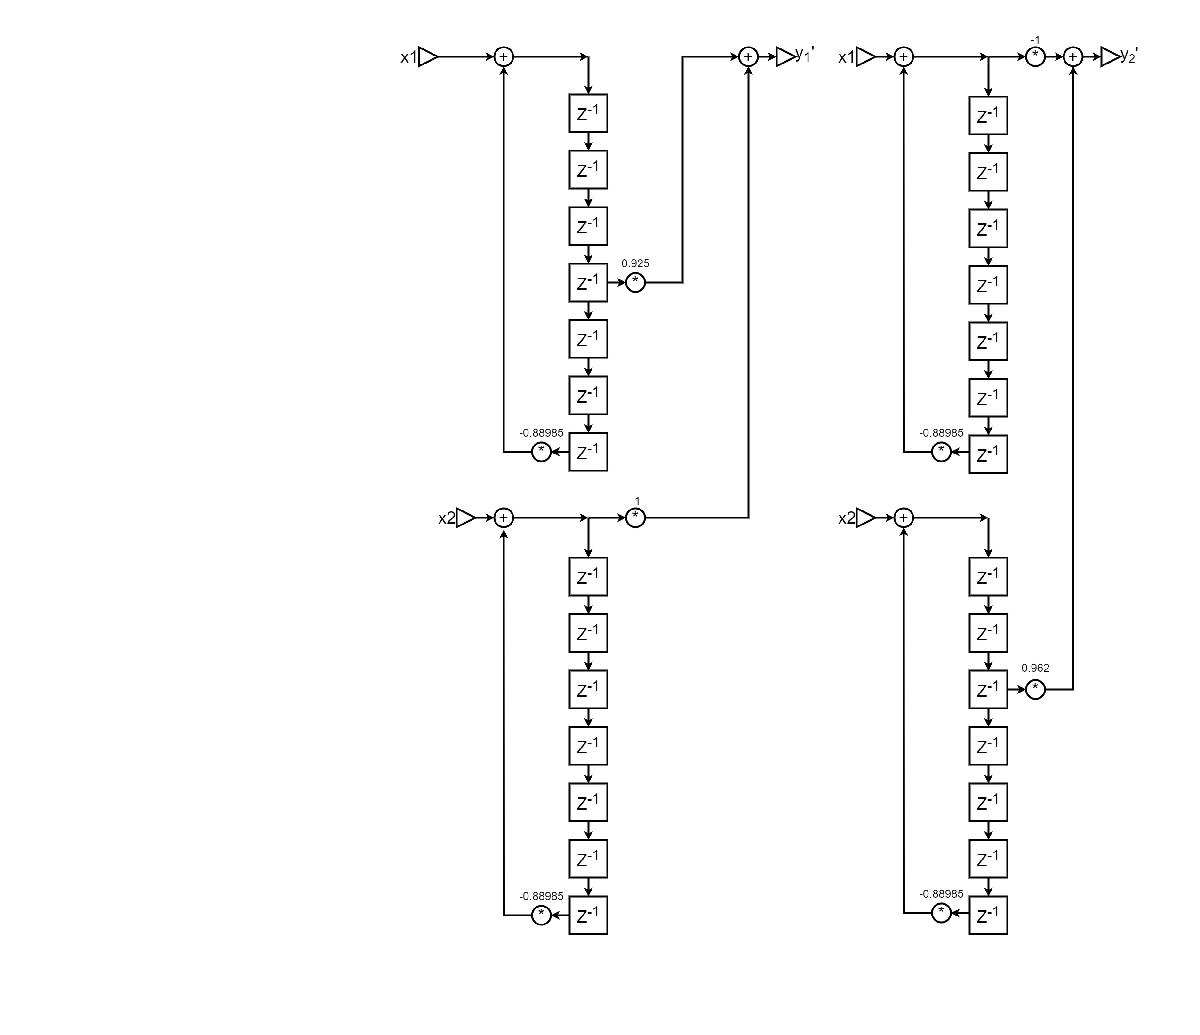

It is clear that the use of delays could be much reduced by merging the paths for each signal. This would look as follows:

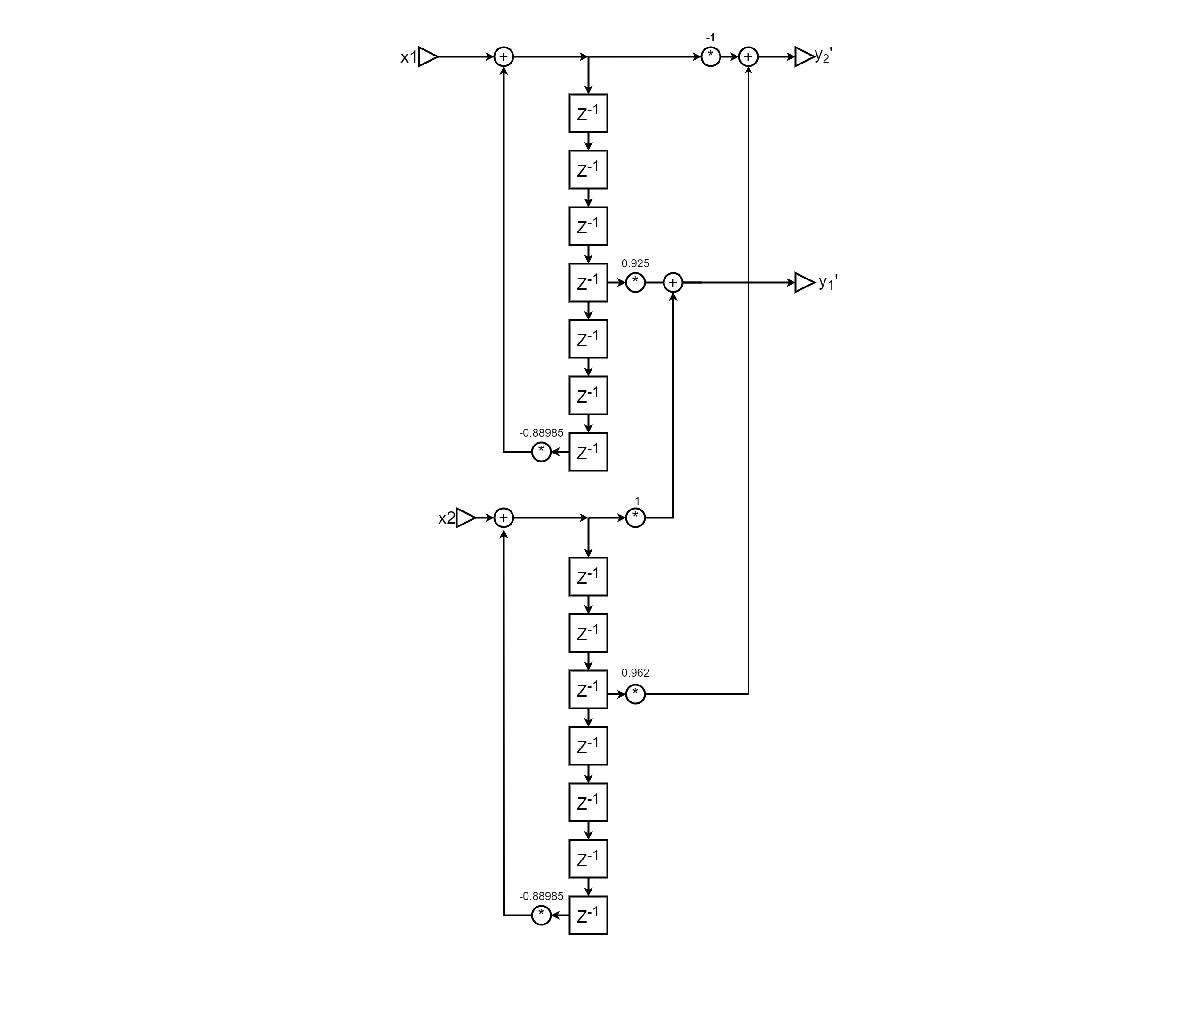

Therefore:


$$\begin{array}{l}
y_1^{\prime } =0\ldotp 925x_1 \left\lbrack n-4\right\rbrack -\left(x_2 -0\ldotp 88985x_2 \left\lbrack n-7\right\rbrack \right)\\
{y_2 }^{\prime } =0\ldotp 962x_2 \left\lbrack n-3\right\rbrack -\left(x_1 -0\ldotp 88985x_1 \left\lbrack n-7\right\rbrack \right)
\end{array}$$


## Question 10

Interference suppression

We will be using an infinite impulse response (IIR) filter as follows:


$$Q\left\lbrack z\right\rbrack =\frac{\left(1-e^{j\Omega_0 } z^{-1} \right)\left(1-e^{-j\Omega_0 } z^{-1} \right)}{\left(1-\gamma e^{j\Omega_0 } z^{-1} \right)\left(1-\gamma e^{-j\Omega_0 } z^{-1} \right)}$$


Expanding the brackets:


$$\begin{array}{l}
Q\left\lbrack z\right\rbrack =\frac{1-\left(e^{-j\Omega_0 } +e^{j\Omega_0 } \right)z^{-1} +z^{-2} }{1-\left(e^{-j\Omega_0 } +e^{j\Omega_0 } \right){\gamma z}^{-1} +\gamma^2 z^{-2} }\\
e^{j\theta } =\cos \theta +\textrm{jsin}\theta \\
e^{-j\theta } =\cos \left(-\theta \right)+\textrm{jsin}\left(-\theta \right)=\cos \theta -\textrm{jsin}\theta \\
e^{j\theta } +e^{-j\theta } =\cos \theta +\textrm{jsin}\theta +\cos \theta -\textrm{jsin}\theta =2\cos \theta \\
Q\left\lbrack z\right\rbrack =\frac{1-2\cos \left(\Omega_0 \right)z^{-1} +z^{-2} }{1-2\cos \left(\Omega_0 \right){\gamma z}^{-1} +\gamma^2 z^{-2} }\\
\therefore b=\left\lbrack 1,-2\cos \left(\Omega_0 \right),1\right\rbrack \;\textrm{and}\;a=\left\lbrack 1,-2\gamma \cos \left(\Omega_0 \right),\gamma^2 \right\rbrack \\
\textrm{where}\;\textrm{the}\;\textrm{normalised}\;\textrm{angular}\;\textrm{frequency}\;\Omega_0 =2\pi \frac{f_0 }{f_s }
\end{array}$$


Gamma = 0.900

b coefficients: b0 = 1.000 b1 = -1.879 b2 = 1.000

a coefficients: a0 = 1.000 a1 = -1.691 a2 = 0.810

Min of -48.87 dB at f=444.0

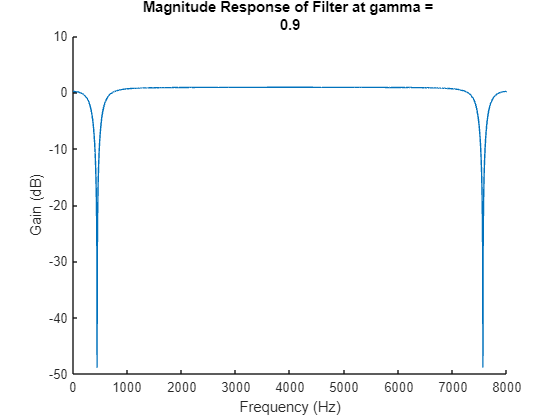

Gamma = 0.990

b coefficients: b0 = 1.000 b1 = -1.879 b2 = 1.000

a coefficients: a0 = 1.000 a1 = -1.861 a2 = 0.980

Min of -29.19 dB at f=444.0

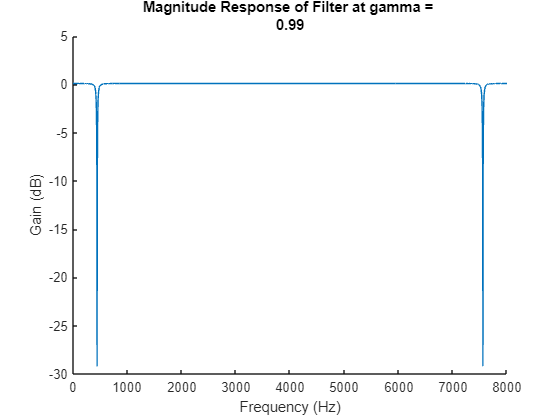

Gamma = 0.999

b coefficients: b0 = 1.000 b1 = -1.879 b2 = 1.000

a coefficients: a0 = 1.000 a1 = -1.878 a2 = 0.998

Min of -9.71 dB at f=444.0

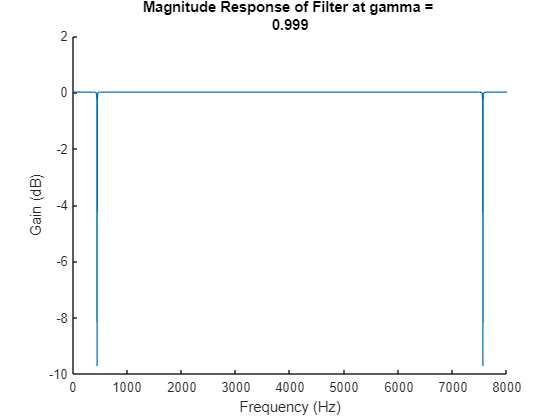

%% Plotting resulting frequency response:
q10_omega0 = 2*pi*444.44/fs; %interference frequency calculated earlier.
%q10_gamma1 = 0.9; %initial value as given in assignment doc
q10_frequencies = 0:8000;
q10_gamma = [0.9,0.99,0.999];
q10_filters = zeros(3,6);

for i = 1:3
    q10_b = [1,-2*cos(q10_omega0),1];
    q10_a = [1,-2*q10_gamma(i)*cos(q10_omega0),q10_gamma(i)^2];
    
    q10_filters(i,:) = [q10_b,q10_a]; % each row of q10_filters contains b0,b1,b2,a0,a1,a2. Each row corresponding to a specific gamma value
    
    %using freqz, from signal processing toolbox
    [q10_h,q10_w] = freqz(q10_b,q10_a,q10_frequencies,fs);
    
    figure
    hold on
        plot(q10_w,20*log10(abs(q10_h))); %from freqz docs

        title(["Magnitude Response of Filter at gamma = ",num2str(q10_gamma(i))]);
        xlabel("Frequency (Hz)")
        ylabel("Gain (dB)")
        fprintf("Gamma = %.3f",q10_gamma(i));
        fprintf("b coefficients: b0 = %.3f b1 = %.3f b2 = %.3f",q10_b);
        fprintf("a coefficients: a0 = %.3f a1 = %.3f a2 = %.3f",q10_a);


        % Find max attenuation, and frequency thereof
        [q10_signal_minima, q10_minima_index] = min(20*log10(abs(q10_h(1:4000))));
        q10_minima_freq = q10_w(q10_minima_index);
        fprintf('Min of %.2f dB at f=%.1f', q10_signal_minima,q10_minima_freq);
        
        fprintf("\n");

     hold off
   

end

As $\gamma \to 1$the attenuation at $f_0$ decreases, and the bandwidth is much tighter.

## Question 11

 Implementing the resulting notch filters:

%% Q11

q11_y_results = zeros(3,2,length(q8_yprime1)); % [gamma value, speaker number, audio sample]
for i = 1:3
    q11_y_results(i,1,:) = filter(q10_filters(i,1:3),q10_filters(i,4:6),q8_yprime1);
    q11_y_results(i,2,:) = filter(q10_filters(i,1:3),q10_filters(i,4:6),q8_yprime2);
end

% play result
q11_gammaselection = input("Please enter gamma selection, 1-3. Integers only: ");
q11_speakerselection = input("Please enter speaker selection, 1-2. Integers only: ");
sound(squeeze(q11_y_results(q11_gammaselection,q11_speakerselection,:)),fs); %squeeze() gets rid of dimensions of size 1


With $\gamma =0\ldotp 9$ the audio feels like there's been a slight high pass filter applied, making it feel thinner.

with $\gamma =0\ldotp 99$ this effect is much reduced. The magnitude of the attenuation is still great enough that the interference is not an issue.

## Question 12

Can we reorder G and Q?

Let's have a look at the phase shift of the filter:

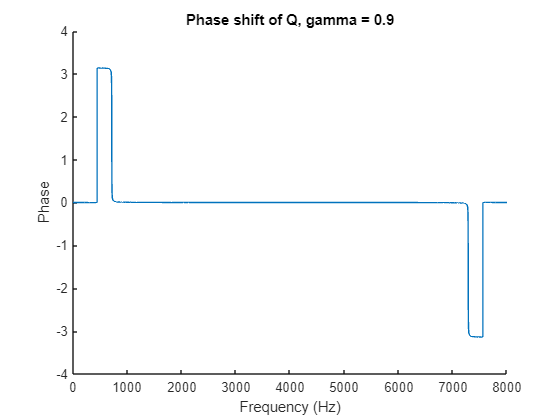

%
q12_b = [1,-2*cos(q10_omega0),1];
q12_a = [1,-2*q10_gamma(1)*cos(q10_omega0),q10_gamma(i)^2];

%using freqz, from signal processing toolbox
[q12_h,q12_w] = freqz(q12_b,q12_a,q10_frequencies,fs);
figure
hold on
title("Phase shift of Q, gamma = 0.9");
xlabel("Frequency (Hz)");
ylabel("Phase");
plot(q12_w,unwrap(angle(q12_h))); %from freqz docs
hold off

There is a definite phase shift at 444Hz to 715Hz. This may affect the delays and gains. Let's see if it does.

q12_x1_filtered = filter(q12_b,q12_a,x1);
q12_x2_filtered = filter(q12_b,q12_a,x2);
q12_G = abs(q12_x2_filtered./q12_x1_filtered);
q12_A = angle(q12_x2_filtered./q12_x1_filtered);

q12_mag_interval_samples = q12_G(1:2000,1);
q12_mag_average_interval = mean(q12_mag_interval_samples((q12_mag_interval_samples >= 0.5) & (q12_mag_interval_samples <= 1.5) ));
fprintf("Average magnitude between 0.5 and 1.5 is: %.3f. Old was: %.3f.",q12_mag_average_interval,q5_mag_average_interval);

Average magnitude between 0.5 and 1.5 is: 0.990. Old was: 0.962.

There is a difference in magnitude here. This would definitely affect the performance of the filter if the coefficients were not changed. This means that you can not swap the order of Q and G without changing the coefficients.